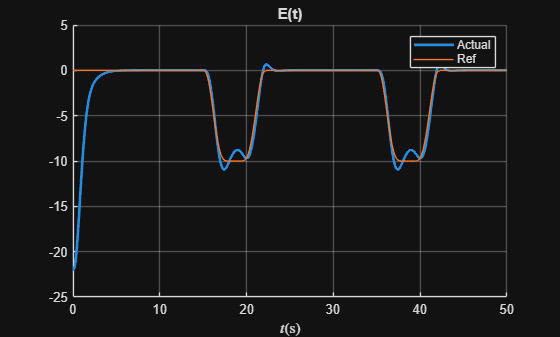

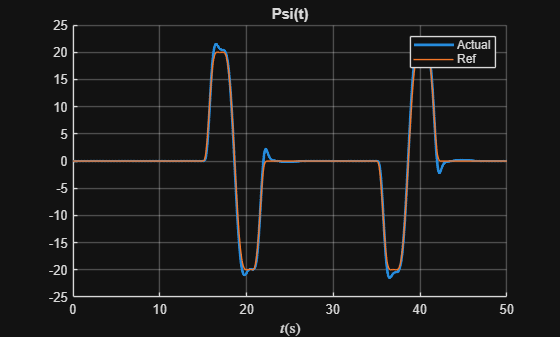

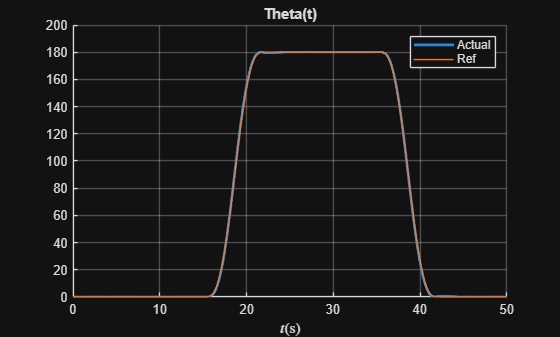

x = x0;
x_bar = x0_bar;
Ie = 0;
It = 0;

tsim = 50;
nsim = round(tsim / Ts); % Simulation steps

x_log = zeros(nx, nsim); % States
u_log = zeros(nu, nsim); % Inputs
tt_log = linspace(0, tsim, nsim);
run_times = zeros(nsim, 1);

nlDynamics = true;

for i = 1 : nsim

    % Add integral states
    Ie = Ie + x(1) - x_opt_ref(1, i);
    It = It + x(3) - x_opt_ref(3, i);

    % x_bar = [x
    %     Ie
    %     It
    % ];
    x_bar = [x
        0
        0
    ];

    ctrl = K_lqr*([x_opt_ref(:,i); 0; 0]-x_bar);

    % Simulate response
    if nlDynamics
        x = x + xUe;
        x = model_nlRK4(f_comb_nl_handle, x, ctrl + U_e_vec, Ts);
        x = x - xUe;
    else
        x = Ad*x + Bd*ctrl;
    end

    % Log
    x_log(:,i) = x;
    u_log(:,i) = ctrl;
end

x_pre_samples = 1:20:length(tt_log); % Display predictions at intervals

for c = 1:3
    figure
    hold on
    plotTimeseries(tt_log, (180/3.14)*x_log(c, :), 'Title', char(X_rb(c)))
    plot(tt_log, (180/3.14)*x_opt_ref(c, 1:nsim))
    hold off
    legend('Actual', 'Ref');
end

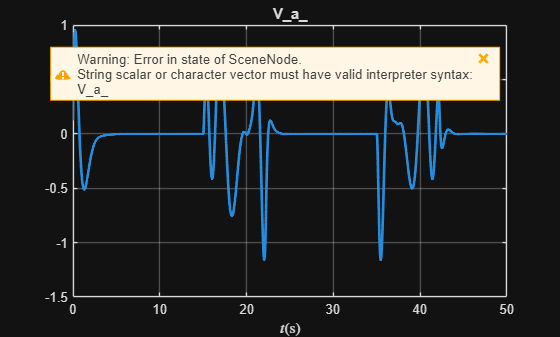

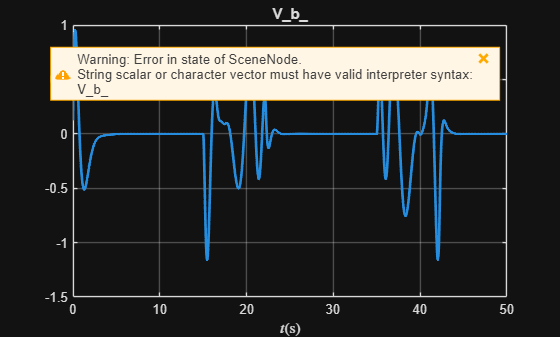

f_pre_samples = 1:50:length(tt_log); % Display predictions at intervals
for c = 7:8
    figure
    plotTimeseries(tt_log, x_log(c, :), 'Title', char(X_comb(c)))
end

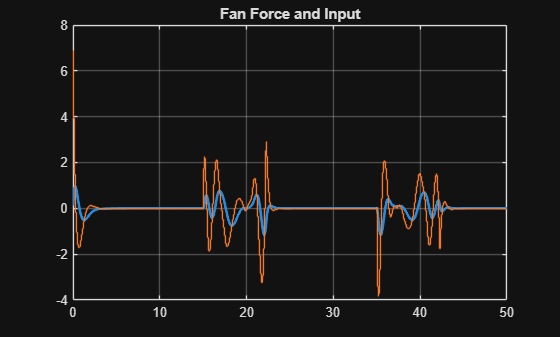

figure
plot(tt_log, x_log(7, :), 'LineWidth', 2)
hold on
stairs(tt_log, u_log(1, :))
title('Fan Force and Input')
grid on
hold off

% plotTimeseries(tt_log, x_log(1:3, :), 'Title', 'Positions')
% plotTimeseries(tt_log, x_log(7:8, :) + F_e_real, 'Title', 'Fan Forces')
% plotTimeseries(tt_log, u_log, 'Title', 'Inputs', 'LineType', 'stairs')